# Exam A Question 2

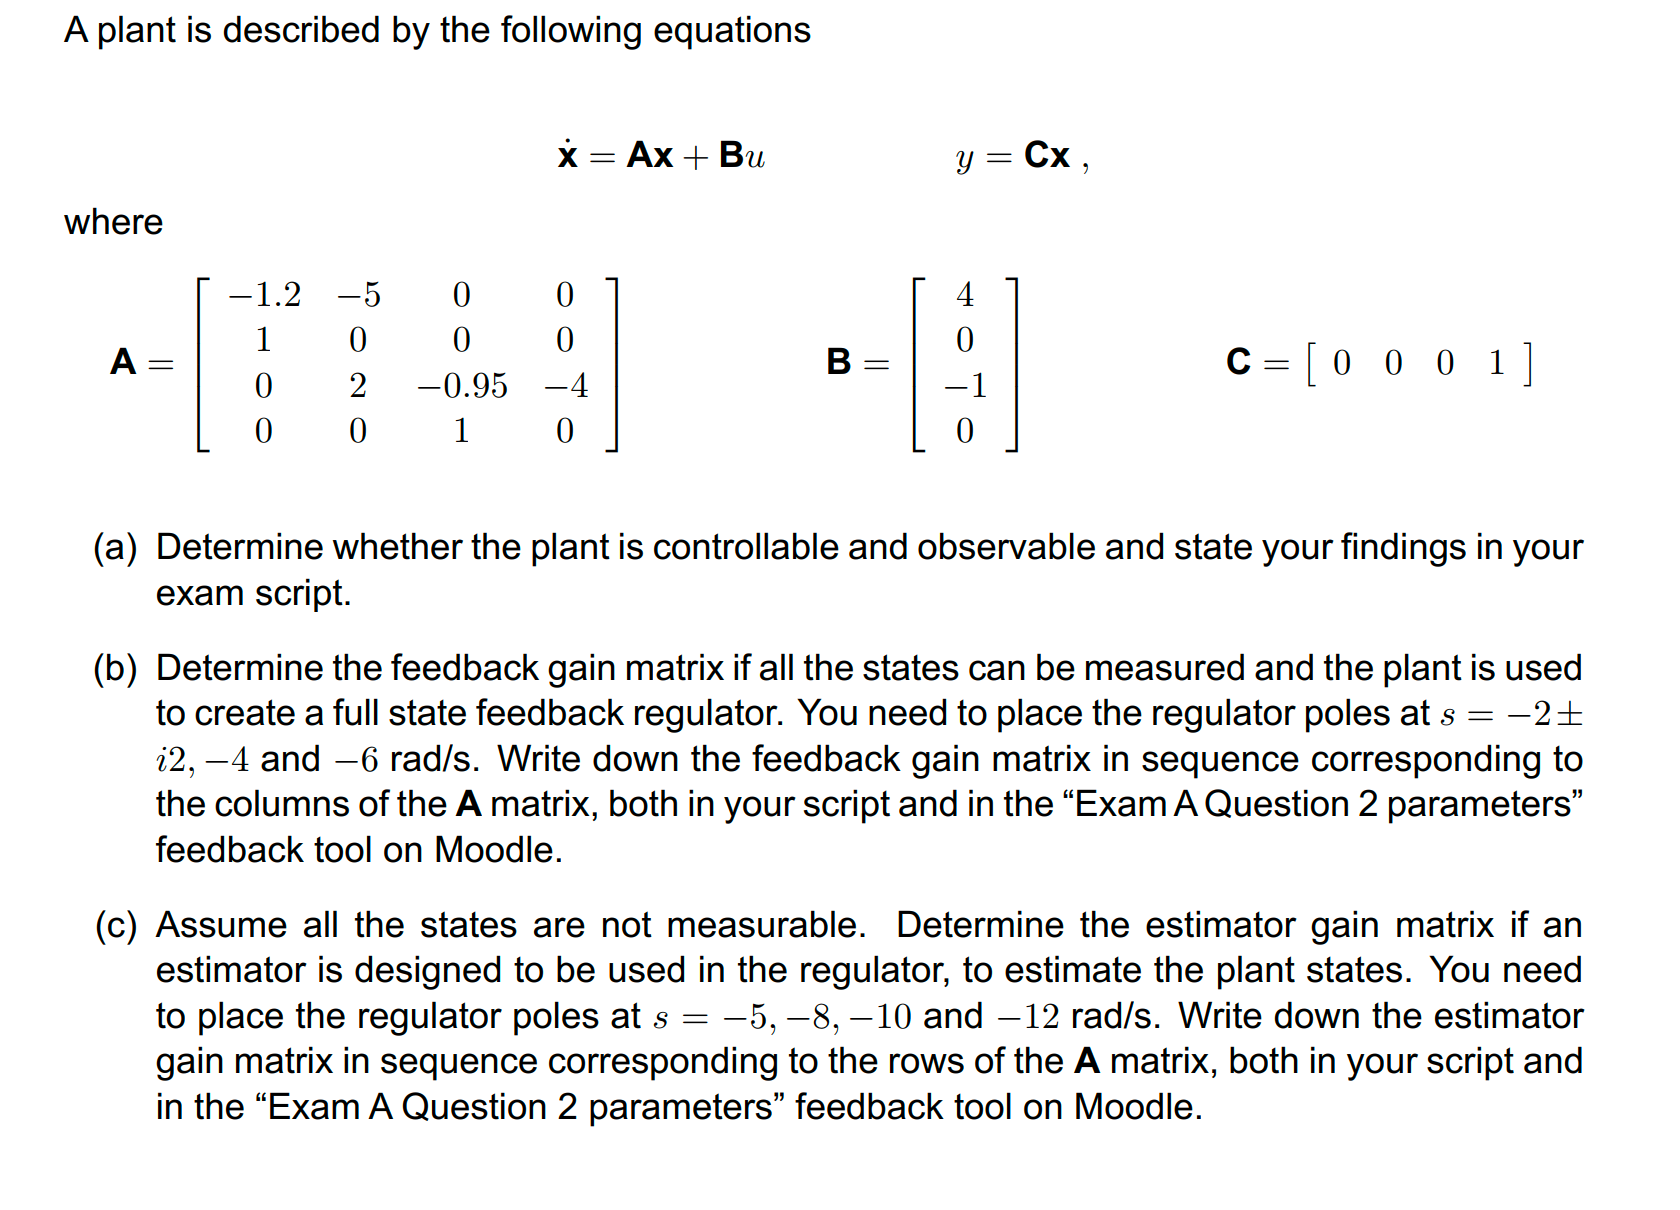

A = [-1.2, -5, 0, 0;
      1,  0, 0, 0;
      0,  2, -0.95, -4;
      0, 0, 1,  0]

A =    -1.2000   -5.0000         0         0
    1.0000         0         0         0
         0    2.0000   -0.9500   -4.0000
         0         0    1.0000         0


B = [4;0;-1;0]

B =      4
     0
    -1
     0


C = [0, 0, 0, 1]

C =      0     0     0     1


D = 0

D = 0

AA = [A B; C 0] ;
bb = [0; 0; 0; 0; 1] ;
 
n = size(A,1);   % 4 states

## (a) check controlability and observability

Ob = obsv(A,C)

Ob =          0         0         0    1.0000
         0         0    1.0000         0
         0    2.0000   -0.9500   -4.0000
    2.0000   -1.9000   -3.0975    3.8000


fprintf('Observability matrix rank: %d (should be %d)\n', rank(Ob), n);

Observability matrix rank: 4 (should be 4)


Cb = ctrb(A,B)

Cb =     4.0000   -4.8000  -14.2400   41.0880
         0    4.0000   -4.8000  -14.2400
   -1.0000    0.9500   11.0975  -23.9426
         0   -1.0000    0.9500   11.0975


fprintf('Controlability matrix rank: %d (should be %d)\n', rank(Cb), n);

Controlability matrix rank: 4 (should be 4)


## (b) Feedback gain matrix

pole1 = -2 + 2*1j ;
pole2 = -2 - 2*1j ;
pole3 = -4 ;
pole4 = -6 ;
K = acker(A,B,[pole1,pole2,pole3,pole4]);
xx = AA \ bb ;

display(["Feedback gain matrix is:", K]) ;

  1×5 string array

    "Feedback gain matrix is:"    "5.36486"    "11.8219"    "9.60945"    "-5.71706"



Nx = xx(1:4) ;
Nu = xx(5) ;
display(Nx);

Nx =          0
    5.3333
         0
    1.0000


display(Nu);

Nu = 6.6667

Nbar = Nu + K * Nx ;
display(Nbar)

Nbar = 64.0000

## (c) All state not measurable

% use the estimator
est_poles = [-5, -8, -10, -12];
L = acker(A', C', est_poles)';
 
fprintf('Estimator gain matrix L =\n');

Estimator gain matrix L =


disp(L);

  324.6168
  895.2360
  365.2325
   32.8500



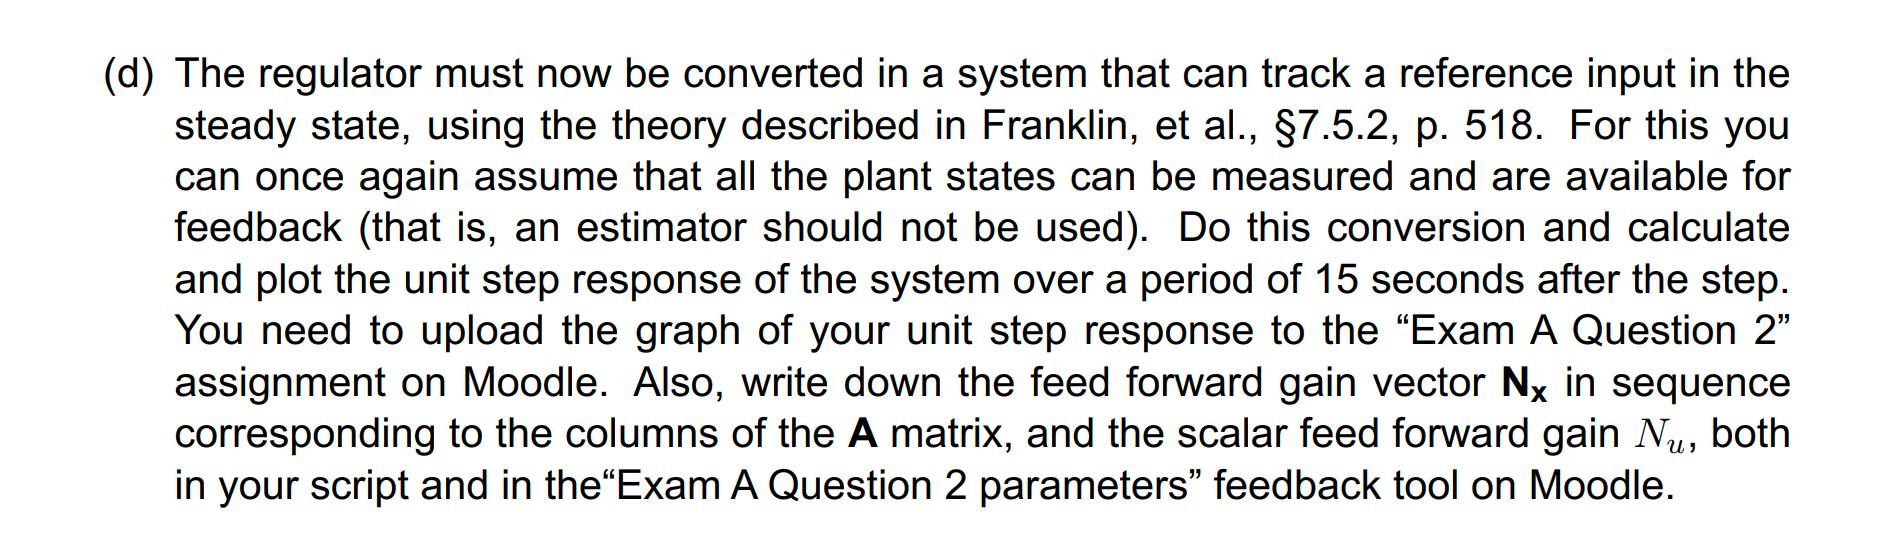


$$u=-\textrm{Kx}+\bar{N} r$$


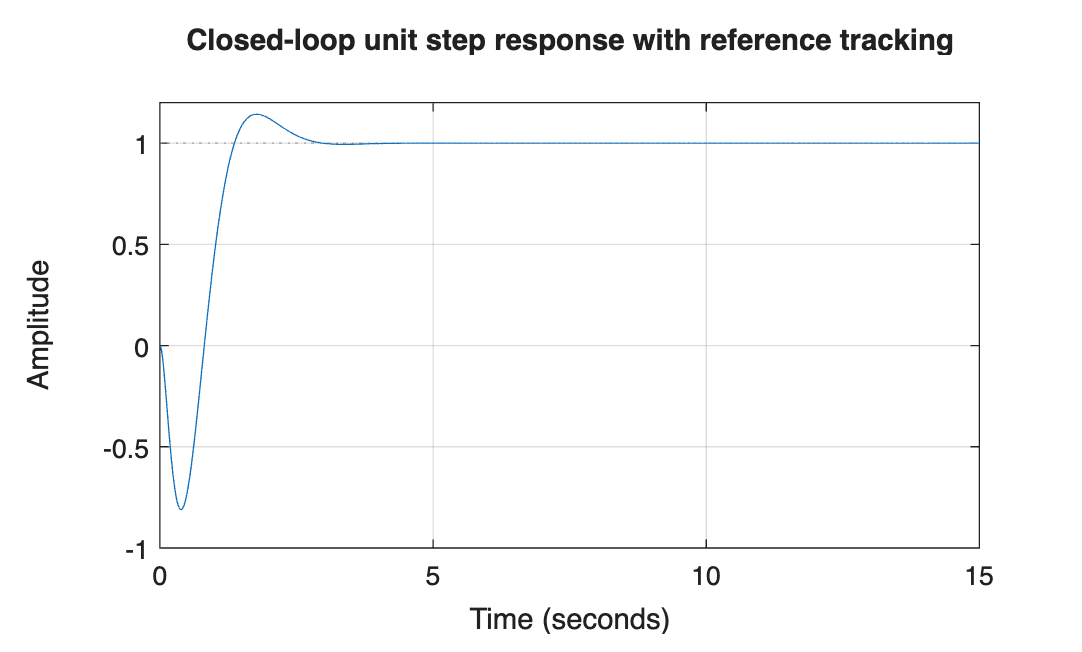

% (d) Reference tracking via Nbar (Franklin §7.5.2)
Acl = A - B*K;
Bcl = B*Nbar;     % Nbar 已经在前面算出来了
Ccl = C;
Dcl = 0;

sys_track = ss(Acl, Bcl, Ccl, Dcl);

figure
step(sys_track, 15)   % 阶跃响应，15秒
grid on
title('Closed-loop unit step response with reference tracking')